% dummy mri data
n = 1000;
x = rand(n,1)*10;
y = rand(n,1)*-10;
s = 0.8 + ...
    sqrt(x.^2 + y.^2)*0.2 + ...
    (rand(n,1)-0.5);

% dummy ephys data
N = 5000;
X = rand(N,1)*10;
Y = rand(N,1)*-10;
S = 3.6 + ...
    sqrt(X.^2 + Y.^2)*0.24 + ...
    1.2*(rand(N,1)-0.5);

figure;
hold on;
scatter3(x,y,s)
scatter3(X,Y,S)

[BETA,SIGMA,RESID] = mvregress([X Y],S);
[beta,sigma,resid] = mvregress([x y],s);

mdl=fitlm([X Y],S)

mdl=fitlm([x y],s)

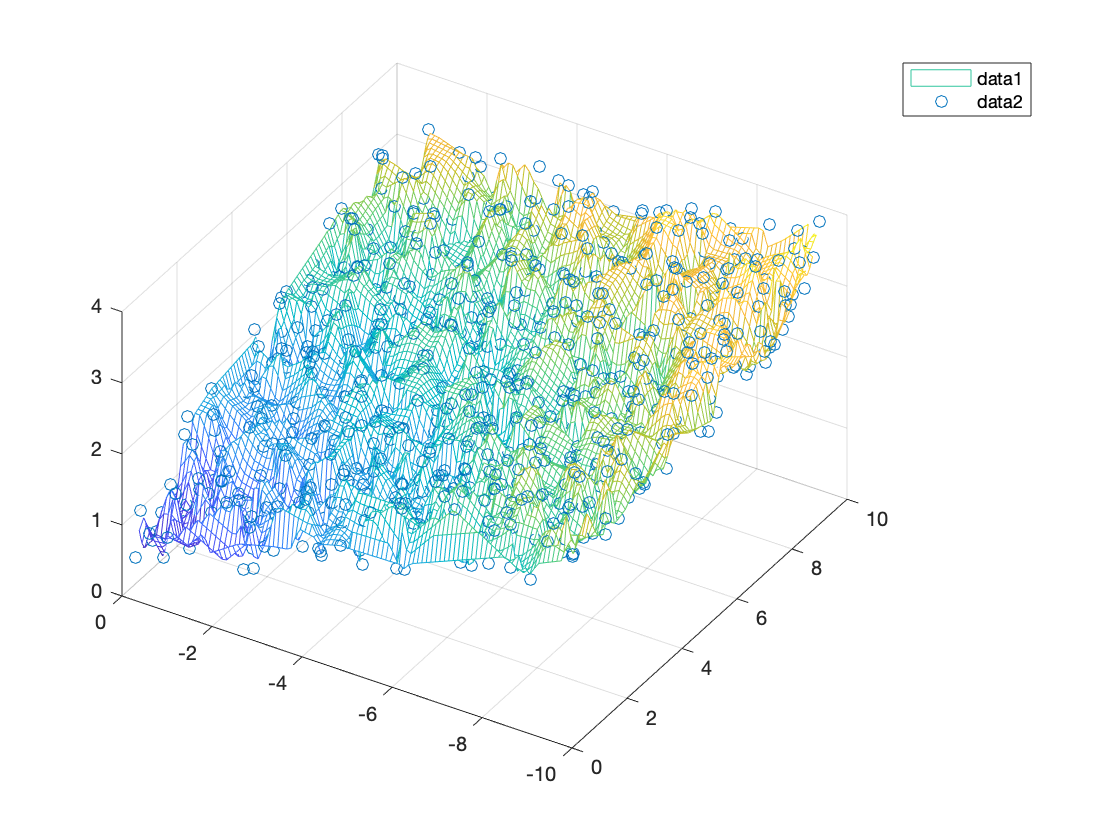

[xq,yq] = meshgrid(0:.1:10,-10:.1:0);
vq = griddata(x,y,s,xq,yq);

mesh(xq,yq,vq); hold on;
plot3(x,y,s,'o')